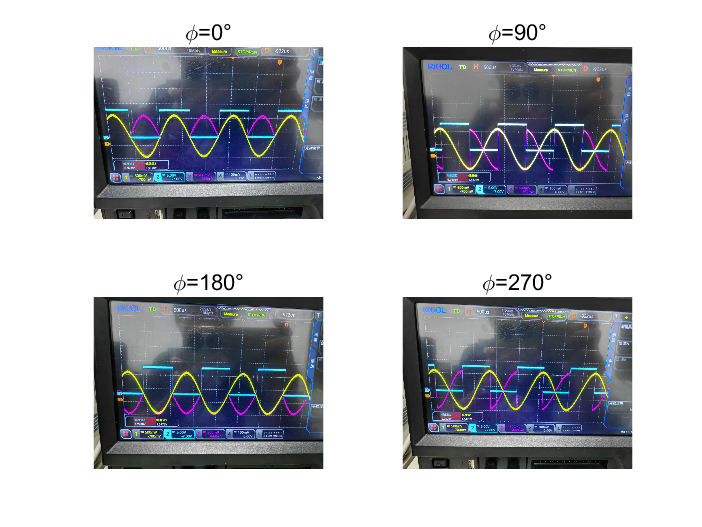

% 读取图像
image1 = imread('phi0.jpg');
image2 = imread('phi90.jpg');
image3 = imread('phi180.jpg');
image4 = imread('phi270.jpg');

% 创建一个新的图形
figure;

% 创建2x2的子图布局
subplot(2, 2, 1);
imshow(image1);
title('\phi=0°');

subplot(2, 2, 2);
imshow(image2);
title('\phi=90°');

subplot(2, 2, 3);
imshow(image3);
title('\phi=180°');

subplot(2, 2, 4);
imshow(image4);
title('\phi=270°');


% 保存图形为JPG文件
saveas(gcf, '参考信号相位拼图.jpg');

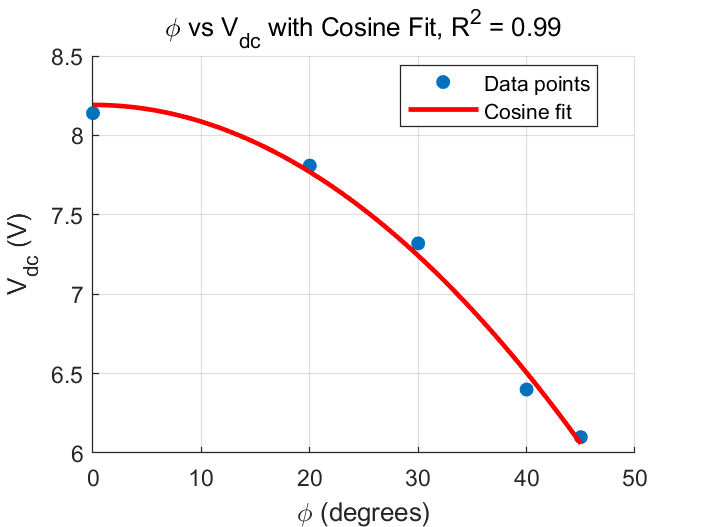

% 数据
Vdc = [8.14, 7.81, 7.32, 6.40, 6.10];
dphi = [0, 20, 30, 40, 45];

% 转换角度为弧度
dphi_rad = deg2rad(dphi);

% 绘制数据点
figure;
scatter(dphi, Vdc, 'filled');
hold on;

% 余弦拟合
fit_result = fit(dphi_rad', Vdc', 'a*cos(b*x)+d', 'StartPoint', [ 1, 1, 1]);
phi_fit = linspace(0, deg2rad(45), 100);
Vdc_fit = feval(fit_result, phi_fit);

% 计算R²值
Vdc_pred = feval(fit_result, dphi_rad);
SS_res = sum((Vdc - Vdc_pred').^2);
SS_tot = sum((Vdc - mean(Vdc)).^2);
R2 = 1 - (SS_res / SS_tot);

% 绘制拟合曲线
plot(rad2deg(phi_fit), Vdc_fit, 'r-', 'LineWidth', 2);

% 图形属性
xlabel('\phi (degrees)');
ylabel('V_{dc} (V)');
title(['\phi vs V_{dc} with Cosine Fit, R^2 = ', num2str(R2, '%.2f')]);
legend('Data points', 'Cosine fit', 'Location', 'Best');
grid on;

% 保存图形为PNG文件
saveas(gcf, 'phi_vs_Vdc_cosine_fit.png');

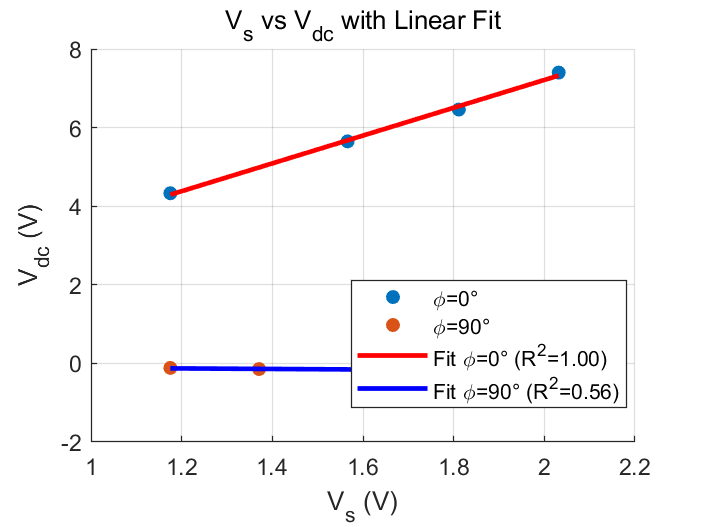

% 数据
Vs_phi0 = [1.175, 1.566, 1.8114, 2.0317];
Vdc_phi0 = [4.33, 5.65, 6.46, 7.4];
Vs_phi90 = [1.175, 1.3707, 1.6155, 1.8848];
Vdc_phi90 = [-0.115, -0.143, -0.180, -0.158];

% 创建图形
figure;

% 绘制phi=0°的数据点
scatter(Vs_phi0, Vdc_phi0, 'filled', 'DisplayName', '\phi=0°');
hold on;

% 绘制phi=90°的数据点
scatter(Vs_phi90, Vdc_phi90, 'filled', 'DisplayName', '\phi=90°');

% 直线拟合phi=0°
p_phi0 = polyfit(Vs_phi0, Vdc_phi0, 1);
Vs_fit_phi0 = linspace(min(Vs_phi0), max(Vs_phi0), 100);
Vdc_fit_phi0 = polyval(p_phi0, Vs_fit_phi0);

% 计算phi=0°的R²值
Vdc_pred_phi0 = polyval(p_phi0, Vs_phi0);
SS_res_phi0 = sum((Vdc_phi0 - Vdc_pred_phi0).^2);
SS_tot_phi0 = sum((Vdc_phi0 - mean(Vdc_phi0)).^2);
R2_phi0 = 1 - (SS_res_phi0 / SS_tot_phi0);

% 直线拟合phi=90°
p_phi90 = polyfit(Vs_phi90, Vdc_phi90, 1);
Vs_fit_phi90 = linspace(min(Vs_phi90), max(Vs_phi90), 100);
Vdc_fit_phi90 = polyval(p_phi90, Vs_fit_phi90);

% 计算phi=90°的R²值
Vdc_pred_phi90 = polyval(p_phi90, Vs_phi90);
SS_res_phi90 = sum((Vdc_phi90 - Vdc_pred_phi90).^2);
SS_tot_phi90 = sum((Vdc_phi90 - mean(Vdc_phi90)).^2);
R2_phi90 = 1 - (SS_res_phi90 / SS_tot_phi90);

% 绘制直线拟合曲线
plot(Vs_fit_phi0, Vdc_fit_phi0, 'r-', 'DisplayName', sprintf('Fit \\phi=0° (R^2=%.2f)', R2_phi0), 'LineWidth', 2);
plot(Vs_fit_phi90, Vdc_fit_phi90, 'b-', 'DisplayName', sprintf('Fit \\phi=90° (R^2=%.2f)', R2_phi90), 'LineWidth', 2);

% 图形属性
xlabel('V_s (V)');
ylabel('V_{dc} (V)');
title('V_s vs V_{dc} with Linear Fit');
legend('Location', 'Best');
grid on;

% 保存图形为PNG文件
saveas(gcf, 'Vs_vs_Vdc_linear_fit.png');

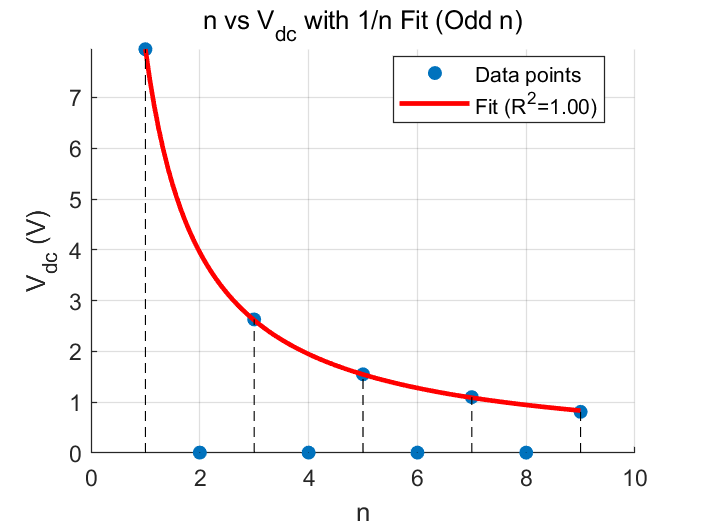

% 数据
n = 1:9;
Vdc = [8.02, 0.078, 2.7, 0.078, 1.62, 0.078, 1.17, 0.078, 0.88];
Vdc_zero = 0.07;

% 扣除零点
Vdc_corrected = Vdc - Vdc_zero;

% 选择奇数的 n
odd_indices = mod(n, 2) == 1;
n_odd = n(odd_indices);
Vdc_odd = Vdc_corrected(odd_indices);

% 创建图形
figure;

% 绘制散点图
scatter(n, Vdc_corrected, 'filled');
hold on;

% 1/n 拟合 (仅对奇数 n)
fit_result = fit((1./n_odd)', Vdc_odd', 'poly1');
n_fit = linspace(min(n_odd), max(n_odd), 100);
Vdc_fit = feval(fit_result, 1 ./ n_fit);

% 计算 R² 值 (仅对奇数 n)
Vdc_pred = feval(fit_result, 1 ./ n_odd);
SS_res = sum((Vdc_odd - Vdc_pred').^2);
SS_tot = sum((Vdc_odd - mean(Vdc_odd)).^2);
R2 = 1 - (SS_res / SS_tot);

% 绘制拟合曲线
plot(n_fit, Vdc_fit, 'r-', 'LineWidth', 2, 'DisplayName', sprintf('Fit (R^2=%.2f)', R2));

% 绘制垂线到x轴
for i = 1:length(n)
    plot([n(i), n(i)], [0, Vdc_corrected(i)], 'k--');
end

% 图形属性
xlabel('n');
ylabel('V_{dc} (V)');
title('n vs V_{dc} with 1/n Fit (Odd n)');
legend({'Data points', sprintf('Fit (R^2=%.2f)', R2)}, 'Location', 'Best');
grid on;
ylim([0 inf]); % 设置 y 轴最小值为 0

% 保存图形为高DPI的PNG文件
print('n_vs_Vdc_fit_odd', '-dpng', '-r1000');